### Parámetros mecanismo 

%constantes
g = 9.81;

%Parámetros Mecánicos
m_m = 0.00339;    % Masa del Motor
m_b = 0.01056;    % Masa del brazo 
Lm = 0.135;     % Distancia hasta el motor 
Lb = 0.056;     % Distancia hasta el centro de masa

torqueB= m_b*Lb; %Torque genrado por el brazo al utilizar el centro de masa general
%torqueB1= m_b2*Lb2-m_b1*Lb1;

J_b = 0.00014;    % Momento de Inercia brazo 
J_m = 1/12*m_m*((11.4*10^-3)^2+(7*10^-3)^2);    % Momento de Inercia Motor
J = J_m + J_b;       % Momento de Inercia Total
betaF = 0.34*2*J;   % Coeficiente de fricción antes estaba en (0.5*2*Jb)
theta_ref = 80;      % Momento de Inercia Total 


Kf = 0.001191 %0.0015404 %Constante del motor (N/%PWM), El valor de Excel lo peta todo: 0.0015 (F/%PWM)

Kf = 0.0012

KPWM_ang = 0.7162;  % PWM/Angulo


## Linealización del sistema

Primero, la ecuación diferencial, es la siguiente:


$$\begin{array}{l}
\dot{x_1 } =x_2 \\
\dot{x_2 =-\frac{\beta }{J}x_2 -\frac{c}{J}\cdot \textrm{sen}\left(x_1 \right)+\frac{a}{J}u} 
\end{array}$$


syms u b c a x1 x2

g = 9.81; %Gravedad
m_m = 0.00339;    % Masa del Motor
m_b = 0.01056;    % Masa del brazo 
l_m = 0.135;     % Distancia hasta el motor 
l_b = 0.056;     % Distancia hasta el centro de masa
J_b = 0.00014;    % Momento de Inercia brazo 
J_m = 1/12*m_m*((11.4*10^-3)^2+(7*10^-3)^2);    % Momento de Inercia Motor
betaF = 0.34*2*J;   % Coeficiente de fricción antes estaba en (0.5*2*Jb)
theta_ref = 60;      % Momento de Inercia Total 
Kf = 0.001191 %0.0015404 %Constante del motor (N/%PWM)

Kf = 0.0012


%Asignar valores a variables simbolicas

J = J_m + J_b;       % Momento de Inercia Total

dx1 = x2

$$dx1 = x_{2}$$

dx2 = -(b/J)*x2 - (c/J)*sind(x1) + (a/J)*u

$$dx2 = \frac{36893488147419103232\,a\,u}{5166953535204153}-\frac{36893488147419103232\,b\,x_{2}}{5166953535204153}-\frac{36893488147419103232\,c\,\sin\left(\frac{\pi \,x_{1}}{180}\right)}{5166953535204153}$$

A = jacobian([dx1;dx2],[x1,x2])

$$A = \left(\begin{array}{cc} 0 & 1\\ -\frac{9223372036854775808\,\pi \,c\,\cos\left(\frac{\pi \,x_{1}}{180}\right)}{232512909084186885} & -\frac{36893488147419103232\,b}{5166953535204153} \end{array}\right)$$

B = jacobian([dx1;dx2],u)

$$B = \left(\begin{array}{c} 0\\ \frac{36893488147419103232\,a}{5166953535204153} \end{array}\right)$$





a = Kf*l_m;
b = betaF;
c = (l_b*m_b+l_m*m_m)*g;

u=theta_ref;
x1 = asind(u*a/c);
x2 = 0;

Aa = eval(A)%Matriz A del sistema linealizado

Aa =          0    1.0000
   -0.4464   -0.6800


Bb = eval(B)%Matriz B del sistema linealizado

Bb =          0
    1.1480


C = [1,0];

[num, den] = ss2tf(Aa,Bb,[1,0;0,1],zeros(2,1))

num =          0         0    1.1480
         0    1.1480         0


den =     1.0000    0.6800    0.4464


s=tf("s");
FuncionTransfer = num(1,3)/(den(1,1)*s^2 + den(1,2)*s + den(1,3))

FuncionTransfer =
 
          1.148
  ---------------------
  s^2 + 0.68 s + 0.4464
 
Continuous-time transfer function.
Model Properties


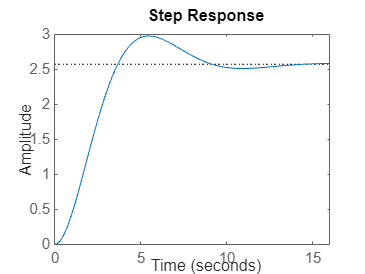

step(FuncionTransfer)


%Polos del sistema
polos_sistema = pole(FuncionTransfer)

polos_sistema =   -0.3400 + 0.5752i
  -0.3400 - 0.5752i


### SMC


%Cotas
J_max = J;
m_m_max = m_m;    
m_b_max = m_b;     
Lm_min = Lm;      
Lb_max = Lb;     
betaF_max = betaF;   
Kf_min = Kf;     


%parámetros simulink
Xr = pi/2;

X2_max = pi;

%beta
a = 1;
beta = (a*J_max-betaF)/(Lm_min*Kf_min)*X2_max  +  (m_m_max + Lb_max*m_b_max/Lm_min)*(g/Kf_min);
beta = ceil(beta);

%beta eq
a_eq = 1;
betaEq = (J_max/(Lm_min*Kf_min)-J/(Lm*Kf))   *   ((a-betaF/J)*X2_max   +   (Lb*m_b +Lm*m_m));
betaEq = ceil(betaEq);

#### Observador continuo

Determinar matriz de observabilidad

O = obsv(Aa, C)

O =      1     0
     0     1


rank(O);%Rango completo, si es observable

polos_deseados = polos_sistema %5 veces más rapidos que el sistema

polos_deseados =   -0.3400 + 0.5752i
  -0.3400 - 0.5752i


%polos_deseados= [-0.34 + 0.5*i , -0.34 - 0.5*i ]; %Tres veces más rapidos que el sistema
%[polos_deseados(1),polos_deseados(2)]
l = acker(Aa',C', polos_deseados)

l = 1.0e-15 *

    0.2220   -0.0555


**Observador discreto**

T_s = 0.01;

sis_estados= ss(Aa, Bb, C, 0); %Representación en espacio de estados del sistema 

sis_discreto = c2d(sis_estados, T_s);  % Discretización del sistema

A_d = sis_discreto.A;
B_d = sis_discreto.B;
C_d = sis_discreto.C;
D_d = sis_discreto.D;

polos_discretos = exp(polos_deseados * T_s)

polos_discretos =    0.9966 + 0.0057i
   0.9966 - 0.0057i




% Ganancias controlador discretas
L_d = (A_d') * l'

L_d = 1.0e-15 *

    0.2223
   -0.0529


### H_inf


%Parámetros H_inf




% % Convertir el sistema a espacio de estados
% [A, B, C, D] = tf2ss(num_G, den_G);
% 
% % Crear el sistema de plantas
% sys_p = ss(A, B, C, D);
% 
% % Definir las matrices de peso para el problema H_inf
% % Aquí creamos una matriz de peso para la entrada y otra para la salida
% W1 = tf([1], [1 0]);  % peso de entrada
% W2 = tf([1], [1 0]);  %  peso de salida
% 
% % Formar el sistema extendido
% sys_ext = sys_p;
% 
% % Crear
% 
% % Crear los sistemas de peso
% sys_w1 = ss(W1);
% sys_w2 = ss(W2);
% 
% % Sistema de entrada y salida combinados
% sys_combined = feedback(series(sys_w1, sys_p), sys_w2);
% 
% % Diseñar el controlador H_inf
% [K,~,~] = hinfsyn(sys_combined, 1, 1);
% 
% % Mostrar el controlador
% disp('Controlador H_inf diseñado:');

%Parámetros H_inf


%num_H = num(1,3);
%den_H = den;
G_0 = FuncionTransfer;

% Convertir el sistema a espacio de estados
[AH, BH, CH, DH] = tf2ss(num(1,3), den);

% Crear el sistema de plantas
P = ss(AH,BH,CH,DH)

P =
 
  A = 
            x1       x2
   x1    -0.68  -0.4464
   x2        1        0
 
  B = 
       u1
   x1   1
   x2   0
 
  C = 
          x1     x2
   y1      0  1.148
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



% Ejemplo de pesos típicos
% W_S: Peso para la función de sensibilidad
Ms = 1.5; % Máxima magnitud permitida de S (alrededor de 6dB)
wb = 10;   % Frecuencia de corte de la banda de rechazo de perturbaciones (rad/s)
Ws = tf([1/Ms, wb], [1, wb*Ms]);

% W_T: Peso para la función de sensibilidad complementaria
Mt = 1.2; % Máxima magnitud permitida de T (alrededor de 2dB)
wt = 10;  % Frecuencia de corte de la banda de rechazo de ruido (rad/s)
Wt = tf([1, wt/Mt], [1/wt, 1]);

% Ws y Wt se pueden ajustar según las especificaciones del sistema

% Crear las matrices de peso en MATLAB
W1 = Ws; % Peso para la función de sensibilidad
W2 = Wt; % Peso para la función de sensibilidad complementaria

% Construir el sistema aumentado para el diseño H∞
systemnames = 'P W1 W2';
inputvar = '[d; u]'; % d: perturbaciones, u: entrada de control
outputvar = '[W1; W2; P]'; % Salidas ponderadas y salida de la planta
input_to_P = '[u + d]'; % Entradas a la planta
input_to_W1 = '[P]'; % Salidas de la planta hacia W1
input_to_W2 = '[u]'; % Controladores a W2

% Definir el sistema interconectado
G = sysic;

% Diseño del controlador H∞ usando hinfsyn
nmeas = size(C, 1); % Número de medidas
ncon = size(B, 2);  % Número de entradas de control

[K, CL, gamma, info] = hinfsyn(G, nmeas, ncon);

% Mostrar el resultado del controlador
disp('El controlador H∞ es:');

El controlador H∞ es:


K

K =
 
  A = 
               x1          x2          x3          x4
   x1     -0.1151     -0.2512  -1.091e-17      0.4458
   x2           1      -0.286           0           0
   x3           0       1.126         -15           0
   x4     -0.1056    -0.04158   3.556e-18      -8.339
 
  B = 
            u1
   x1  0.02702
   x2   0.2491
   x3  0.01891
   x4        0
 
  C = 
             x1        x2        x3        x4
   y1   -0.0264  -0.01039  8.89e-19    0.4153
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


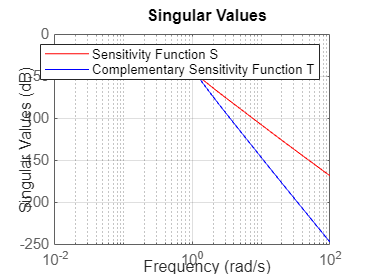


% Evaluar la respuesta del sistema cerrado
T = feedback(P*K, eye(size(K, 1)));

% Plotear las funciones de sensibilidad y sensibilidad complementaria
figure;
sigma(T, 'r', T*P, 'b');
legend('Sensitivity Function S', 'Complementary Sensitivity Function T');
grid on;



%%Gráficas
% time = out.Comparacion_lin_nolin.time;
% signal1 = out.Comparacion_lin_nolin.signals(1).values;
% signal2 = out.Comparacion_lin_nolin.signals(2).values;
% figure;
% plot(time, signal1, 'r', 'DisplayName', 'Entrada 1');
% hold on;
% plot(time, signal2, 'b', 'DisplayName', 'Entrada 2');
% legend('Modelo no linealizado', 'Modelo linealizado')
% hold off;
% figure(1)
% plot(out.x1.time,out.x1.signals.values)
% legend("Referencia", "Posición")
% figure(2)
% plot(out.x2.time,out.x2.signals.values)
% figure(3)
% plot(out.dx2.time,out.dx2.signals.values)


h_inf = K

h_inf =
 
  A = 
               x1          x2          x3          x4
   x1     -0.1151     -0.2512  -1.091e-17      0.4458
   x2           1      -0.286           0           0
   x3           0       1.126         -15           0
   x4     -0.1056    -0.04158   3.556e-18      -8.339
 
  B = 
            u1
   x1  0.02702
   x2   0.2491
   x3  0.01891
   x4        0
 
  C = 
             x1        x2        x3        x4
   y1   -0.0264  -0.01039  8.89e-19    0.4153
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


h_inf_discreto = c2d(K, T_s)

h_inf_discreto =
 
  A = 
               x1          x2          x3          x4
   x1      0.9988   -0.002508  -1.012e-19    0.004274
   x2     0.00998      0.9971  -5.183e-22   2.165e-05
   x3   5.353e-05     0.01044      0.8607   7.889e-08
   x4   -0.001015   -0.000397    3.17e-20        0.92
 
  B = 
               u1
   x1    0.000267
   x2    0.002489
   x3   0.0001889
   x4  -6.411e-07
 
  C = 
             x1        x2        x3        x4
   y1   -0.0264  -0.01039  8.89e-19    0.4153
 
  D = 
       u1
   y1   0
 
Sample time: 0.01 seconds
Discrete-time state-space model.
